%load images and labels
crop_size = 72;
[test, train, test_labels, train_labels] = load_images(crop_size);

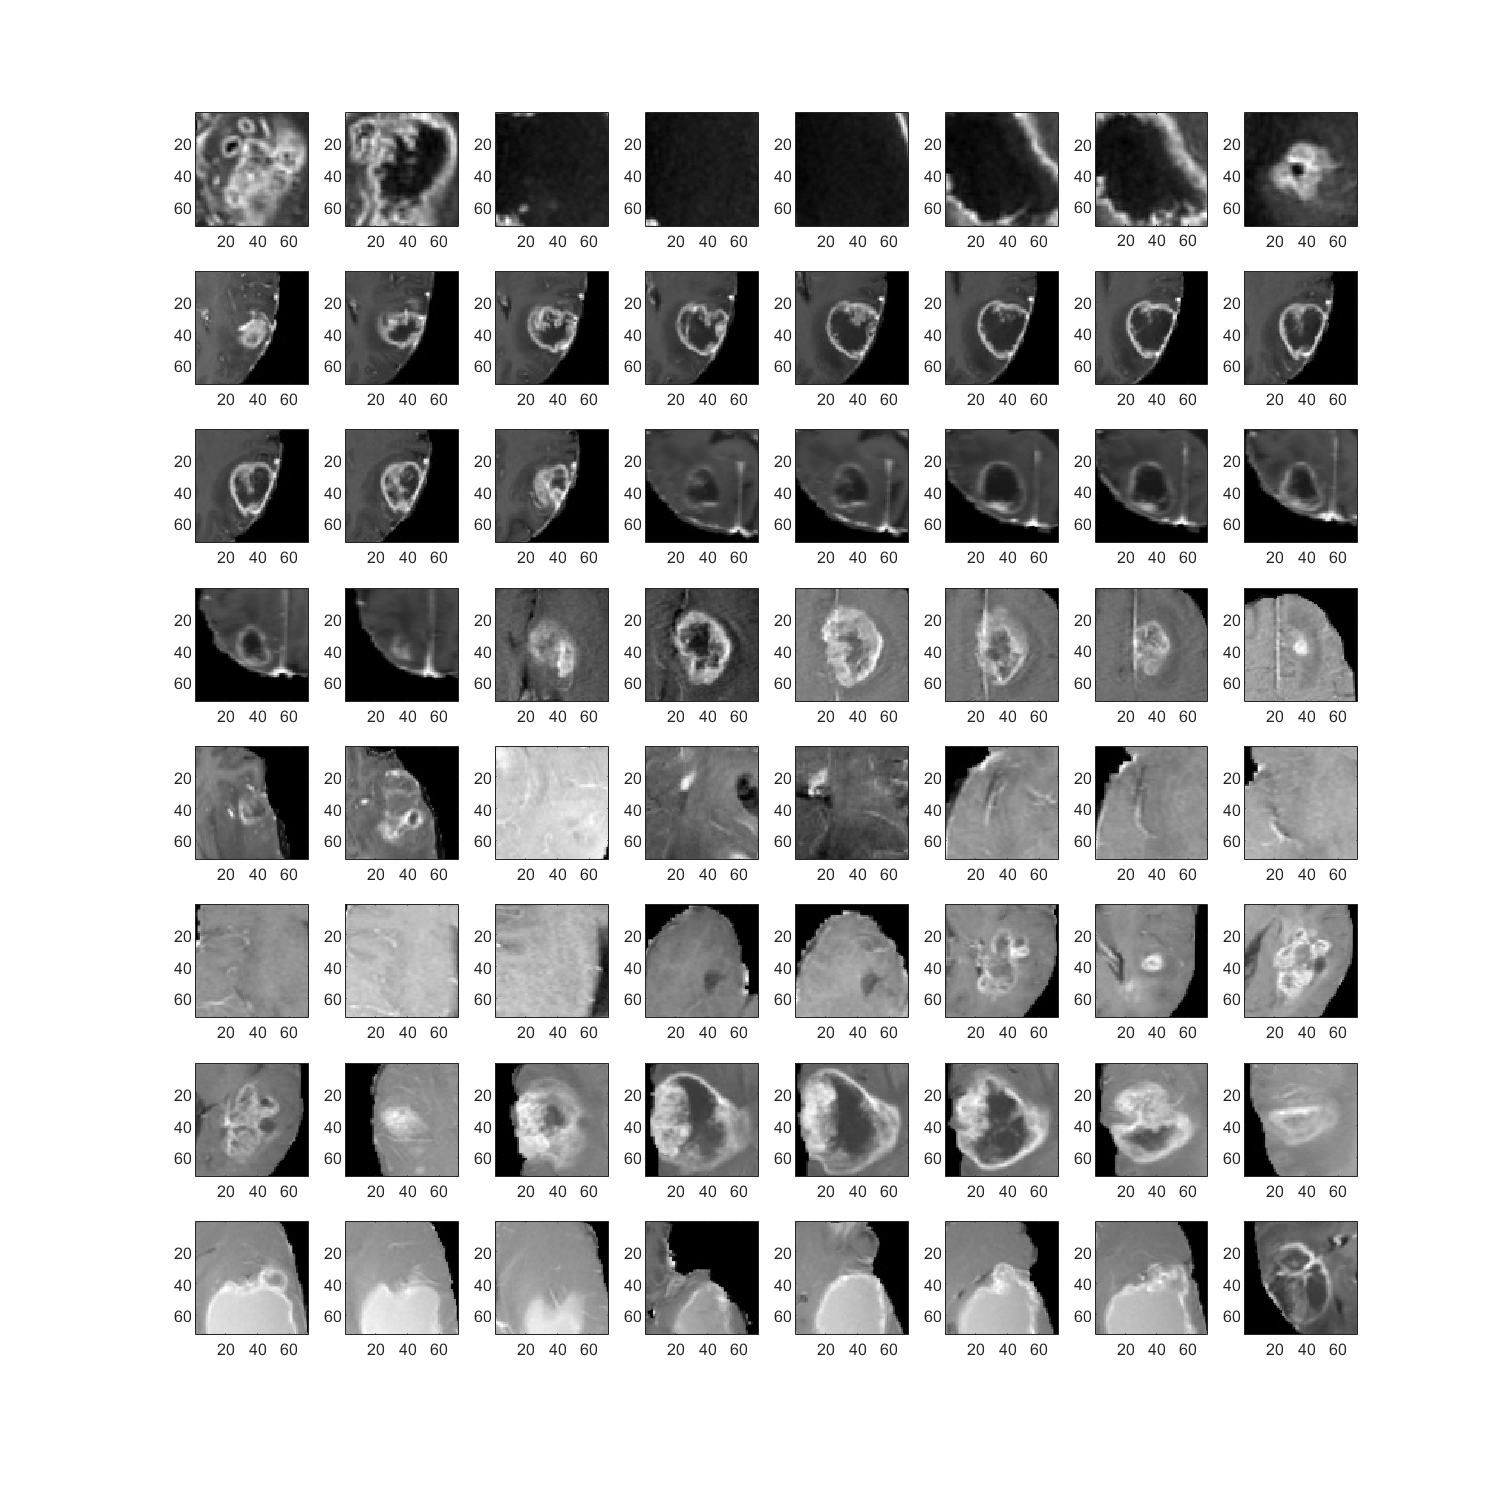

%plot
figure(1)
clf
set(figure(1), "Position", [0 0 1000 1000])
 for i=1:64
     subplot(8,8,i)
     imagesc(reshape(train(i,:), crop_size, crop_size))
     axis equal
 end
 colormap 'gray'

%PCA
 train_mc = train - mean(train);
 R = train_mc' * train_mc;
 [V, D] = eigs(R, 20);

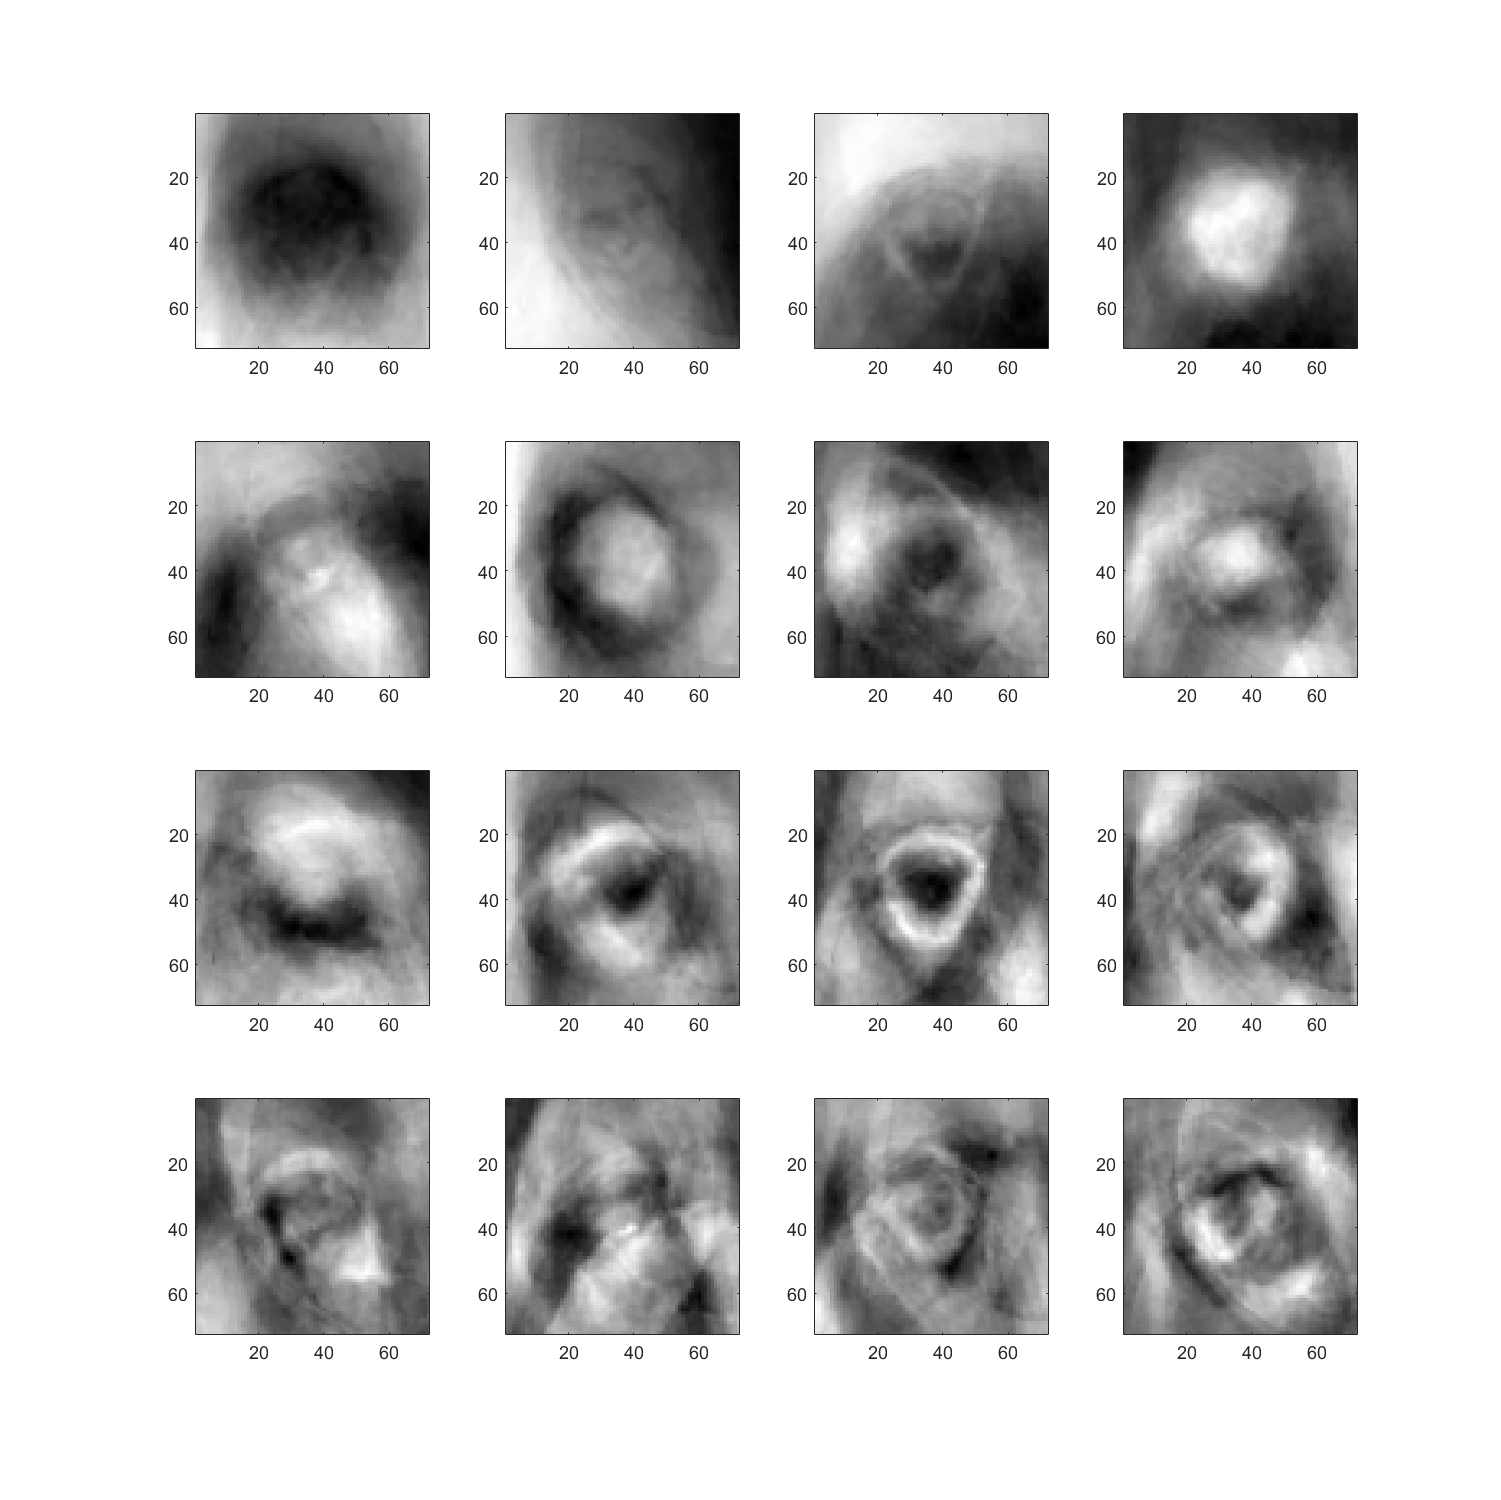

%plot tumor space
 figure(2)
 clf
clf
set(figure(2), "Position", [0 0 1000 1000])
 for i=1:16
     subplot(4,4,i)
     imagesc(reshape(V(:,i), crop_size, crop_size))
     axis equal
 end
 colormap 'gray'

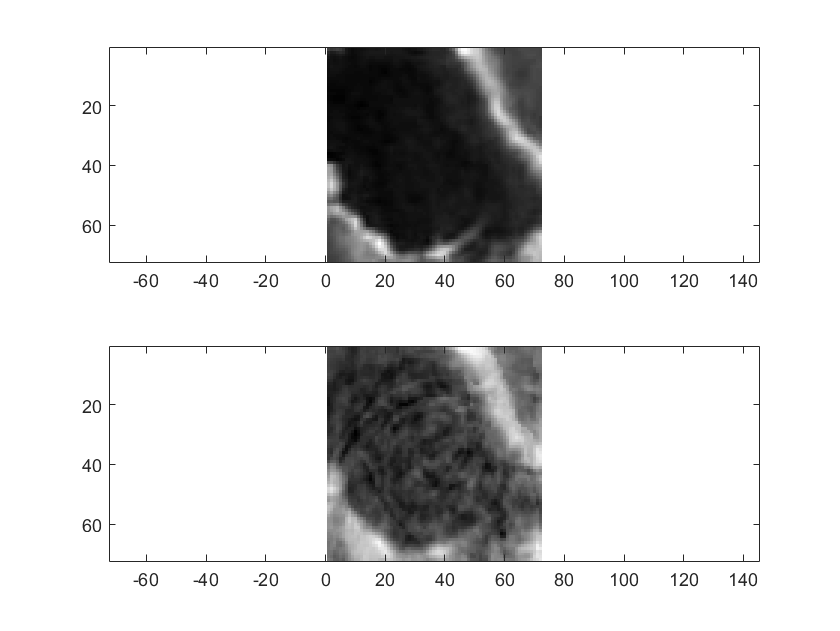


train_comp = train*V;
train_restr = train_comp * V';


i = 6;
figure(3)
clf
subplot(2,1,1)
imagesc(reshape(train(i,:), crop_size, crop_size))
axis equal
subplot(2,1,2)
imagesc(reshape(train_restr(i,:), crop_size, crop_size))
colormap 'gray'
axis equal


norm(train(i,:) - train_restr(i,:))

ans = 539.7491

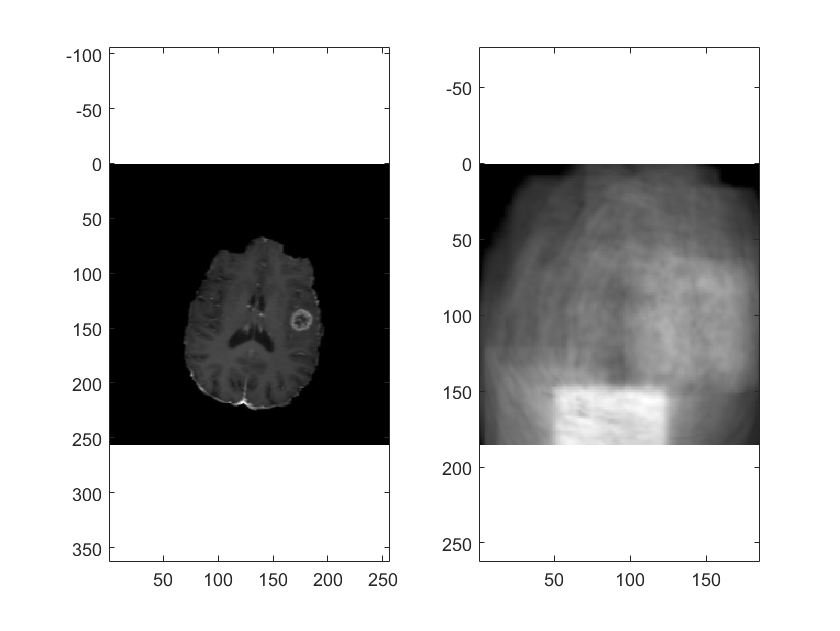


heat_map = zeros(256-crop_size, 256-crop_size);

wholeimage = reshape(test(25,:), 256, 256);


for i=1:256 - crop_size + 1
     for j=1:256 - crop_size + 1



         subimage = wholeimage(i:crop_size-1+i, j:crop_size-1+j);
        
        
         subimage = reshape(subimage, 1, 72^2);
         
         si_comp = subimage * V;
         si_restr  = si_comp * V';
         
         epsilon = norm(si_restr - subimage);
         heat_map(i, j) = epsilon;
         
     end
 end
 
 
figure(4)
clf
subplot(1,2,1)
imagesc(wholeimage)
axis equal
subplot(1,2,2)
imagesc(heat_map)
axis equal
colormap 'gray'


i = 0;
j = 0;


Gamma = reshape(test(1,:), 256, 256);
Gamma = Gamma(1+i:crop_size+i, 1+j:crop_size+j);
Gamma = reshape(Gamma, [], 1);
Psi = transpose(1 / 288 * sum(train));

c1 = 2 * corr(Gamma, Psi);
c2 = corr(Gamma, V);
c3 = corr(Psi, V);

epsilon = (Gamma'* Gamma) - c1 + (Psi' * Psi) + sum(c2 - c3);

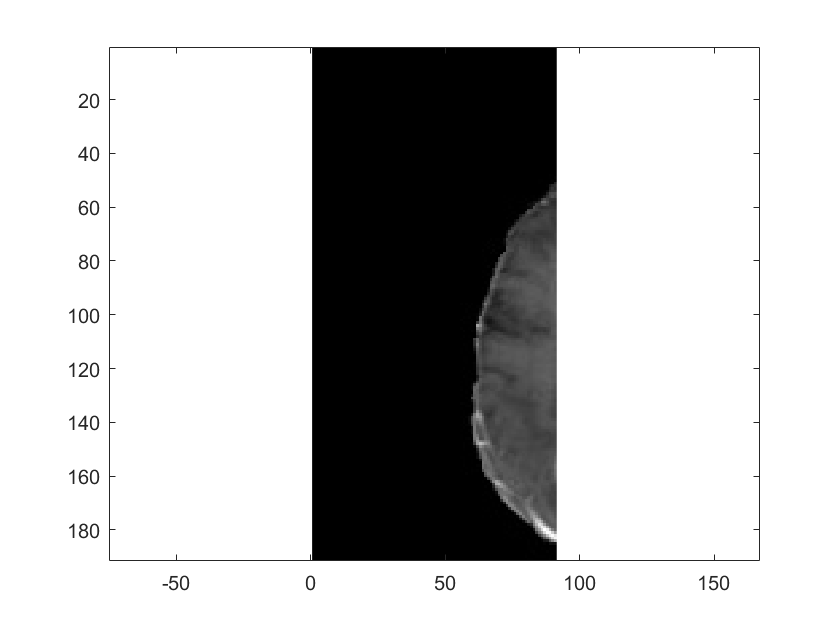


a = wholeimage(10:200, 10:100);
clf
imagesc(a)
axis equal